# ASTE 580 HW4

## Problem 1

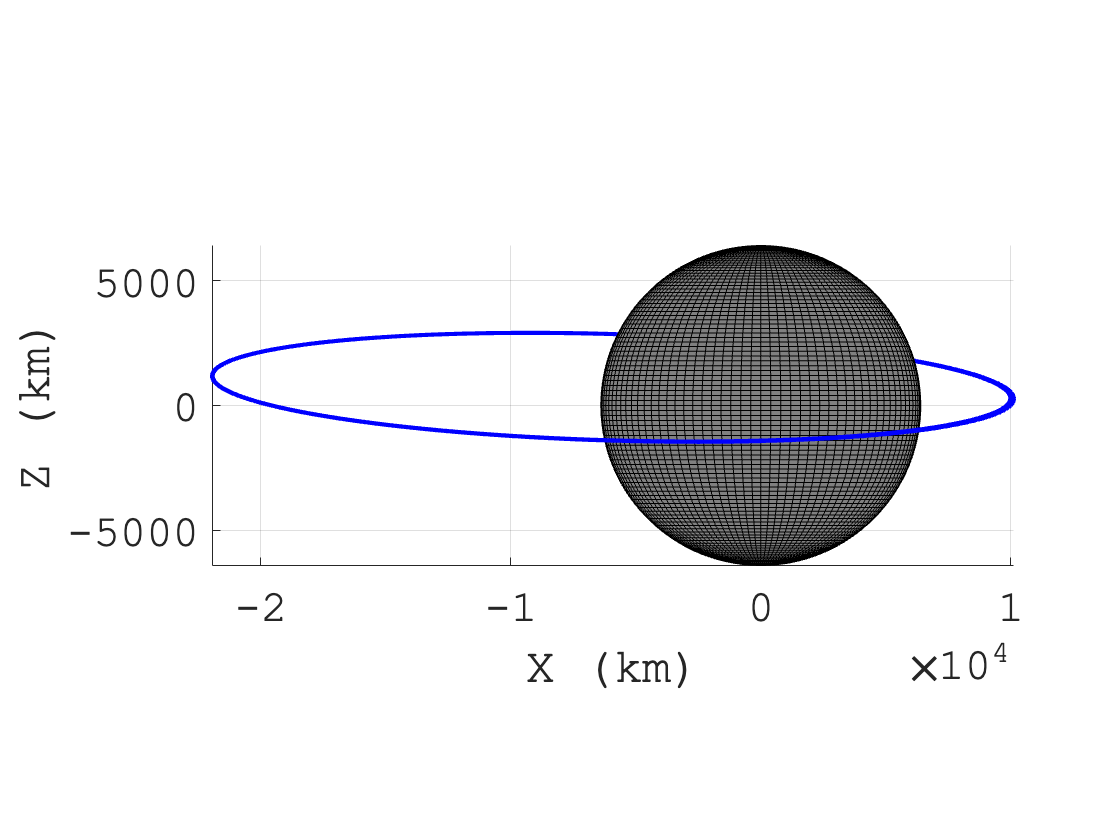

R = 6400; %km
mu = 3.986e5; %km^3/s^2

r0 = [10000;1000;0];
v0 = [1;sqrt(mu/10000)+1;1];
E_func = @(r,v) norm(v)^2/2-mu/norm(r); %kJ/kg
h_func = @(r,v) norm(cross(r,v)); %km^2/s
a = - mu/(2*E_func(r0,v0));
T = 2*pi*sqrt(a^3/mu);
tspan = [0:10*60:10*T];

options = odeset('RelTol',1.0e-6,'InitialStep',1.0e-6,'AbsTol',1.0e-6);
[t,X] = ode45(@odefunc,tspan,[r0(1),r0(2),r0(3),v0(1),v0(2),v0(3)],options);

plot3(X(:,1),X(:,2),X(:,3),'b','linewidth',2);
hold on;
[x,y,z] = sphere(100);
x = x*R;
y = y*R;
z = z*R;
surf(x,y,z,'EdgeColor','k','FaceColor','#808080');
axis equal;
grid on;
set(gcf,'Color','w');
set(gca,'Color','w');
set(gca,'FontSize',22,'FontName','Courier New');
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
view(0,0);
hold off;

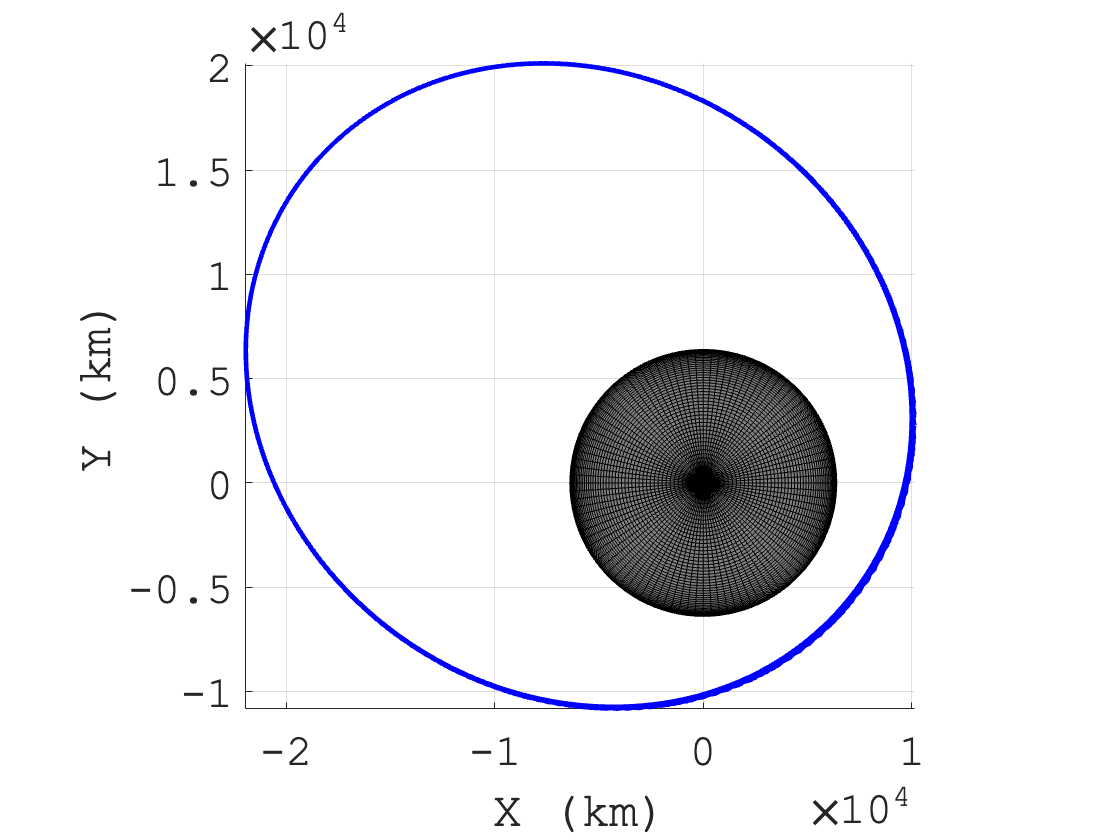

plot3(X(:,1),X(:,2),X(:,3),'b','linewidth',2);
hold on;
[x,y,z] = sphere(100);
x = x*R;
y = y*R;
z = z*R;
surf(x,y,z,'EdgeColor','k','FaceColor','#808080');
axis equal;
grid on;
set(gcf,'Color','w');
set(gca,'Color','w');
set(gca,'FontSize',22,'FontName','Courier New');
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
view(0,90);
hold off;

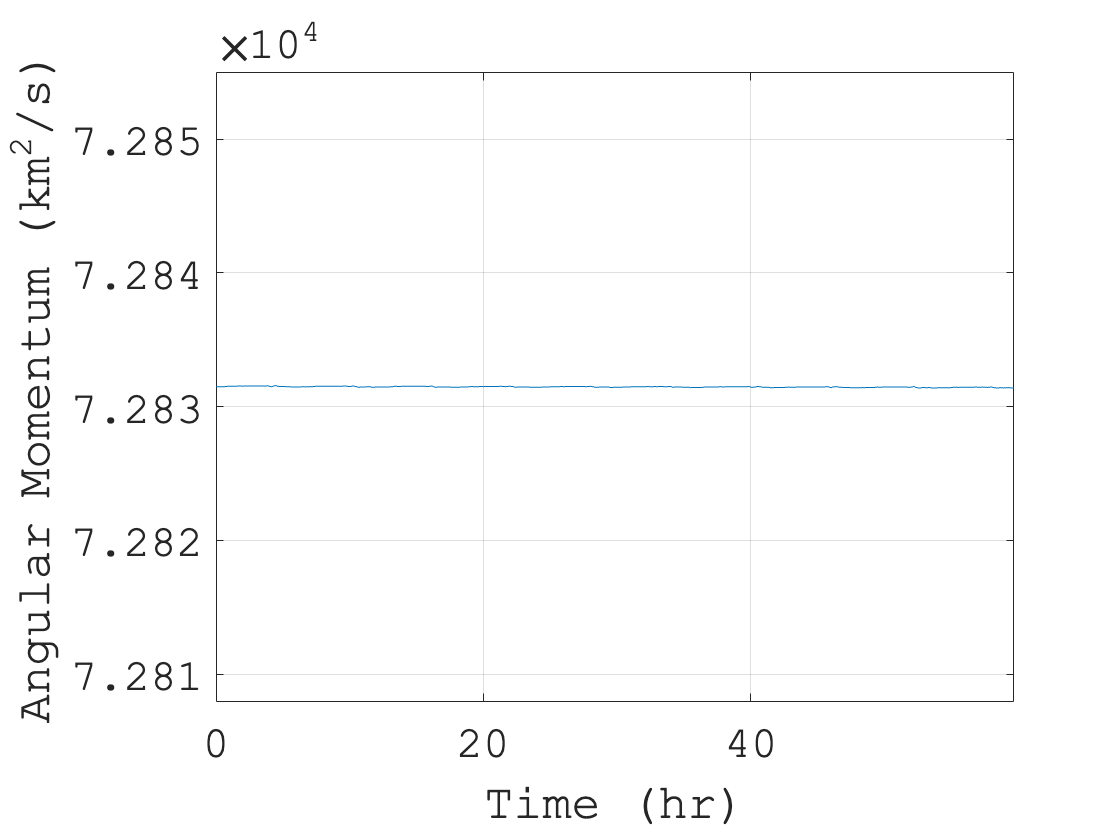

len = size(X,1);
E = zeros(len,1);
h = zeros(len,1);
for i = 1:len
    r = [X(i,1);X(i,2);X(i,3)];
    v = [X(i,4);X(i,5);X(i,6)];
    E(i) = E_func(r,v);
    h(i) = h_func(r,v);
end
plot(t/3600,h);
hold on;
axis equal;
grid on;
set(gcf,'Color','w');
set(gca,'Color','w');
set(gca,'FontSize',22,'FontName','Courier New');
xlabel('Time (hr)');
ylabel('Angular Momentum (km^2/s)');
hold off;

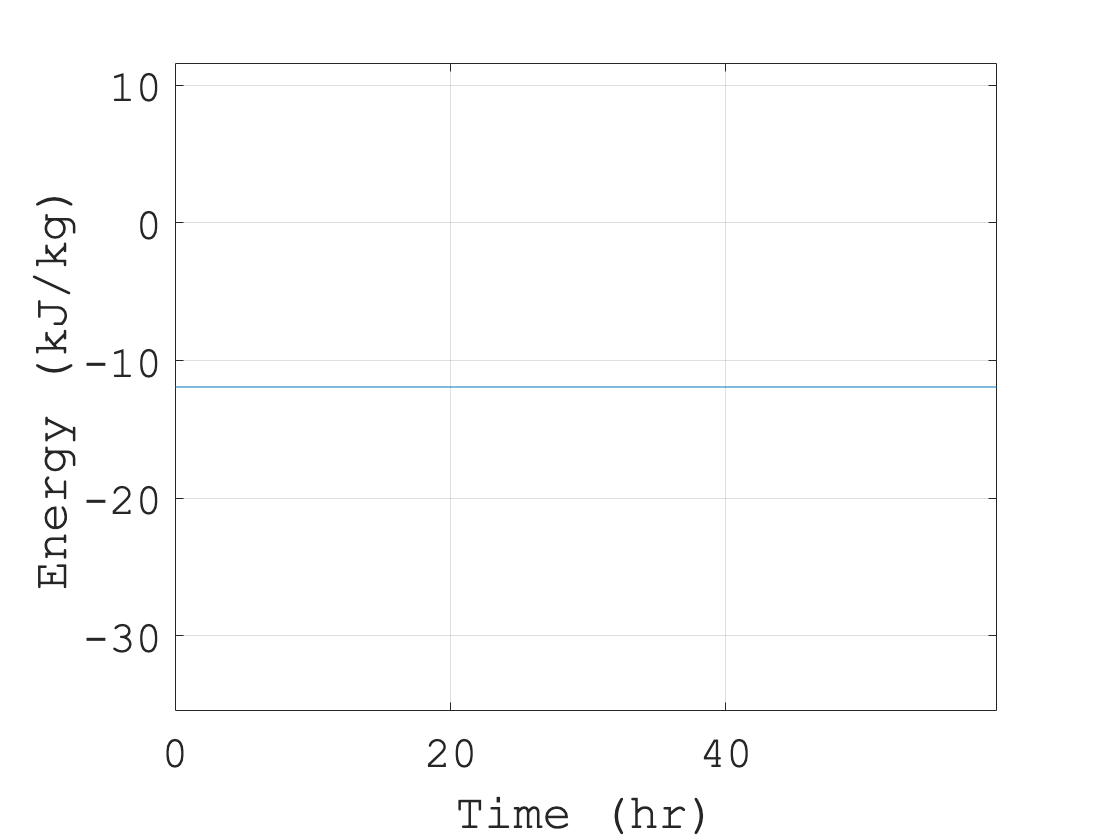

plot(t/3600,E);
hold on;
axis equal;
grid on;
set(gcf,'Color','w');
set(gca,'Color','w');
set(gca,'FontSize',22,'FontName','Courier New');
xlabel('Time (hr)');
ylabel('Energy (kJ/kg)');
hold off;

function Xdot = odefunc(~,X)
mu = 3.986e5; %km^3/s^2

x = X(1);
y = X(2);
z = X(3);
xdot = X(4);
ydot = X(5);
zdot = X(6);
r = [X(1);X(2);X(3)];

Xdot(1,1) = xdot;
Xdot(2,1) = ydot;
Xdot(3,1) = zdot;
Xdot(4,1) = -mu * x / norm(r)^3;
Xdot(5,1) = -mu * y / norm(r)^3;
Xdot(6,1) = -mu * z / norm(r)^3;
end